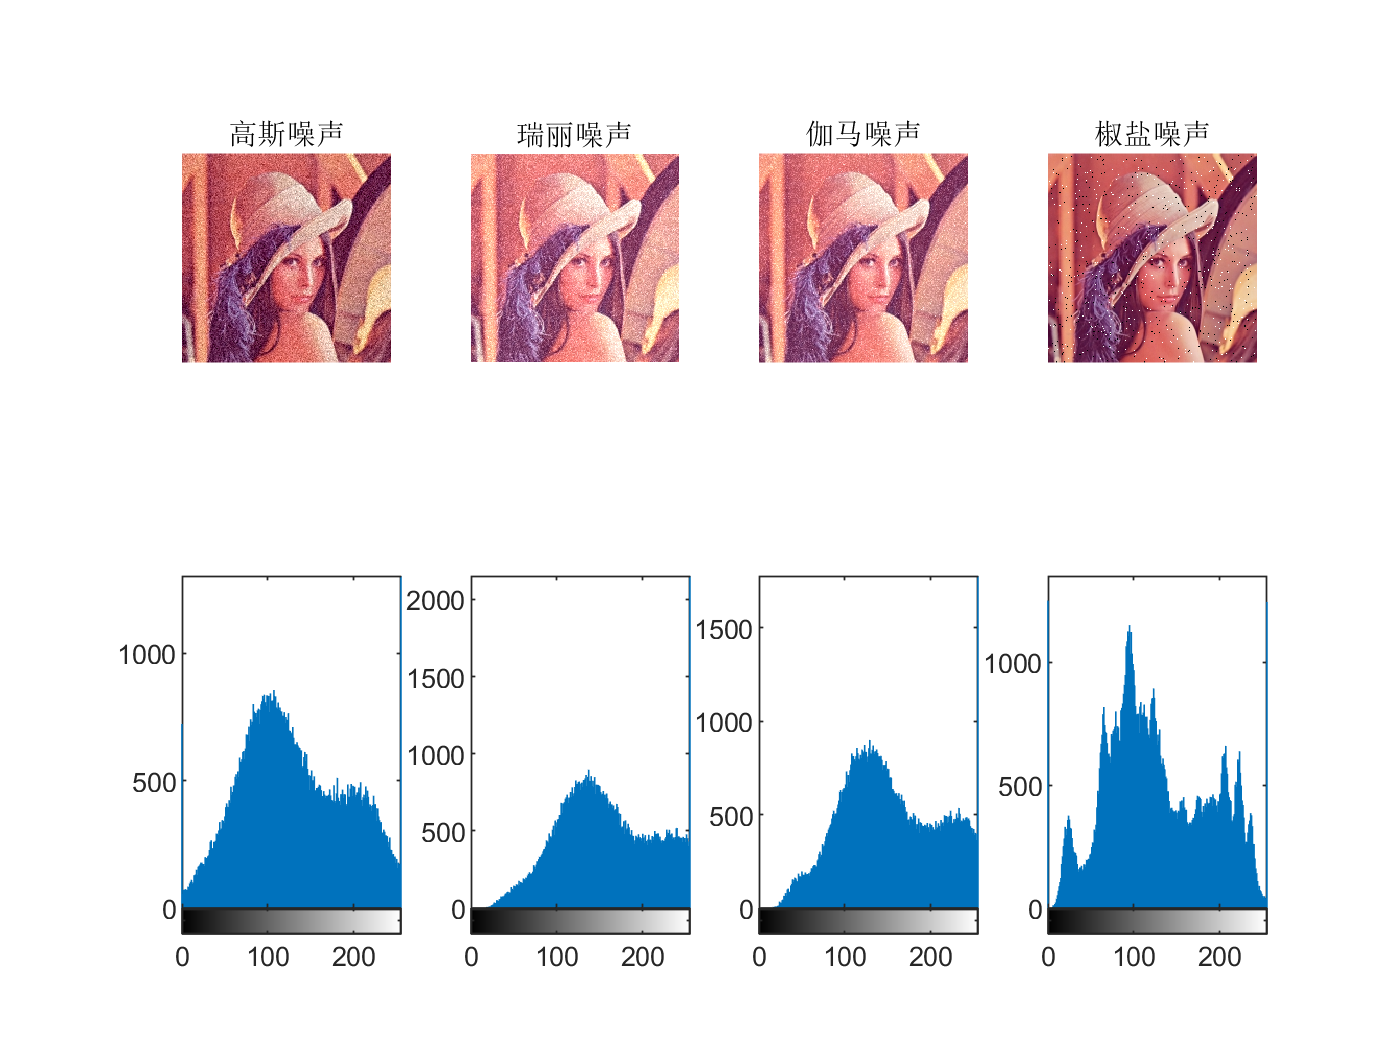

img = imread("lena.jpg");
[l,w,~] = size(img);
img = double(img);

figure;
noise_gaussian = normrnd(3,20,l,w);
img_guss = img + noise_gaussian;
subplot(241);
imshow(uint8(img_guss));
title('高斯噪声');
subplot(245);
imhist(uint8(img_guss));

noise_rayleigh = raylrnd(30,l,w);
img_rayl = img + noise_rayleigh;
subplot(242);
imshow(uint8(img_rayl));
title('瑞丽噪声');
subplot(246);
imhist(uint8(img_rayl));

noise_gamma = gamrnd(3,10,l,w);
img_gama = img + noise_gamma;
subplot(243);
imshow(uint8(img_gama));
title('伽马噪声');
subplot(247);
imhist(uint8(img_gama));

a = 0.01; b = 0.01;
X = rand(l,w); Y = rand(l,w);
c = X <= a;
noise_saltpepper = c;
c = Y >= 1-b;
noise_saltpepper = noise_saltpepper - 2*c;
img_sp = img + 255*noise_saltpepper;
subplot(244);
imshow(uint8(img_sp));
title('椒盐噪声');
subplot(248);
imhist(uint8(img_sp));


figure;
% subplot(141);
% imshow(uint8(ari_filter(img_sp, 3)));
% title('3*3算数均值滤波器');
% subplot(142);
% imshow(uint8(geo_filter(img_sp, 3)));
% title('3*3几何均值滤波器');
% subplot(143);
% imshow(uint8(invhar_filter(img_sp, 3, 1.5)));  
% title('3*3 Q=1.5 逆谐波滤波器');
% subplot(144);
% imshow(uint8(invhar_filter(img_sp, 3, -1.5)));  
% title('3*3 Q=-1.5 逆谐波滤波器');
% 
% figure;
% subplot(141);
% imshow(uint8(ari_filter(img_guss, 3)));
% title('3*3算数均值滤波器');
% subplot(142);
% imshow(uint8(geo_filter(img_guss, 3)));
% title('3*3几何均值滤波器');
subplot(143);
imshow(uint8(invhar_filter(img_guss, 3, 1.5)));  

title('3*3 Q=1.5 逆谐波滤波器');
subplot(144);
imshow(uint8(noise_filter('contra_harmonic',img_guss, [3, 1.5])));  

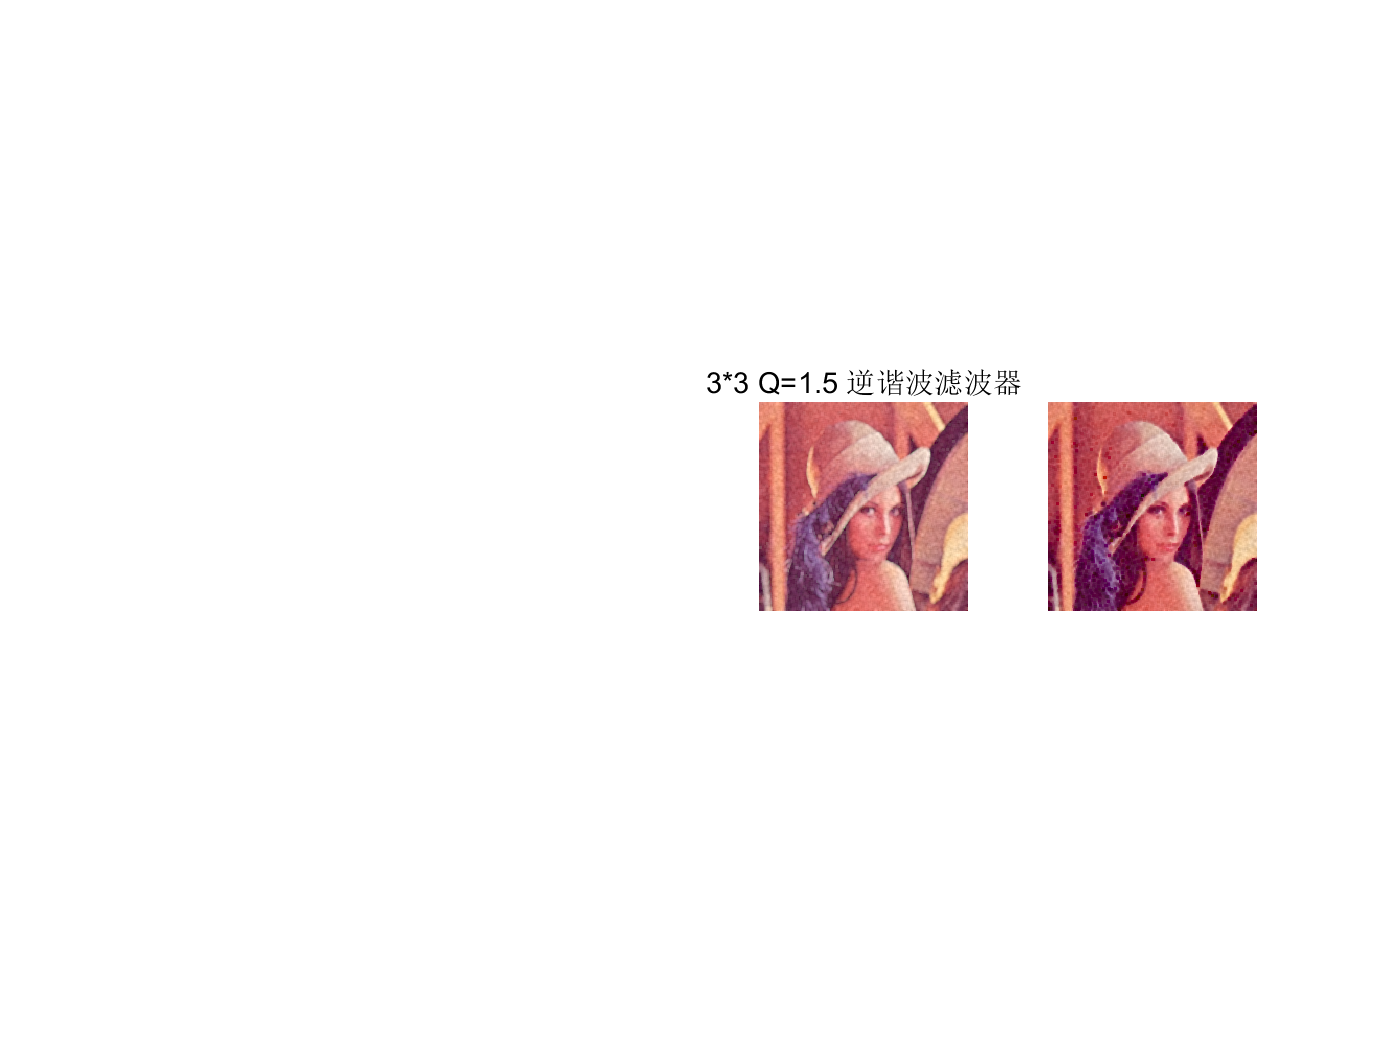


imshow(uint8(invhar_filter(img_guss, 3, -1.5)));  

title('3*3 Q=-1.5 逆谐波滤波器');

figure;
img_sp_guss = img_guss + 255*noise_saltpepper;
imshow(uint8(img_sp_guss));
figure;
subplot(241);
imshow(uint8(ari_filter(img_sp_guss, 3)));
title('3*3算数均值滤波器');
subplot(242);
imshow(uint8(geo_filter(img_sp_guss, 3)));
title('3*3几何均值滤波器');
subplot(243);
imshow(uint8(invhar_filter(img_sp_guss, 3, 1.5)));  
title('3*3 Q=1.5 逆谐波滤波器');
subplot(244);
imshow(uint8(invhar_filter(img_sp_guss, 3, -1.5)));  
title('3*3 Q=-1.5 逆谐波滤波器');
subplot(245);
imshow(uint8(ari_filter(invhar_filter(img_sp_guss, 3, 1.5), 3)));
title('1.5逆谐波+算术均值');
subplot(246);
imshow(uint8(ari_filter(invhar_filter(img_sp_guss, 3, -1.5), 3)));
title('-1.5逆谐波+算术均值');
subplot(247);
imshow(uint8(geo_filter(invhar_filter(img_sp_guss, 3, 1.5), 3)));
title('1.5逆谐波+几何均值');
subplot(248);
imshow(uint8(geo_filter(invhar_filter(img_sp_guss, 3, -1.5), 3)));
title('-1.5逆谐波+几何均值');

img = imread("lena.jpg");
[l,w,ch] = size(img);
figure;
subplot(2,5,1);
imshow(img);
xlabel('原图像');
img_fft = fft2(im2double(img));
img_fft = fftshift(img_fft);
img_fft = abs(img_fft);
img_fft = log(img_fft+1);
mmax = max(max(max(img_fft)));
mmin = min(min(min(img_fft)));
img_fft = 255*img_fft./(mmax-mmin);
subplot(2,5,6);
imshow(uint8(img_fft));

for k = 1:ch
   for i = 1:l
      for j = 1:w        
          img(i,j,k) = img(i,j,k) + 30*sin(30*i)+30*sin(30*j);
      end
   end
end
subplot(2,5,2);
imshow(img);
xlabel('添加噪声后图像');
img_fft0 = fft2(im2double(img));
img_fft0 = fftshift(img_fft0);

img_fft = abs(img_fft0);
img_fft = 30*log(img_fft+1);
subplot(2,5,7);
imshow(uint8(img_fft));


%带阻滤波器
img_fft0_ideal = band_filter(img_fft0,'ideal',[l,w,ch],44.5,9);
subplot(2,5,3);
img_ifft0 = ifftshift(img_fft0_ideal);
img_ifft0 = ifft2(img_ifft0);
img_ifft = abs(img_ifft0);
img_ifft = log(img_ifft+1);
mmax = max(max(max(img_ifft)));
mmin = min(min(min(img_ifft)));
img_ifft = 255*img_ifft./(mmax-mmin);
imshow(uint8(img_ifft));
xlabel('ideal去噪');

img_ifftfft = abs(img_fft0_ideal);
img_ifftfft = 30*log(img_ifftfft+1);
subplot(2,5,8);
imshow(uint8(img_ifftfft));

img_fft0_butw = band_filter(img_fft0,'butterworth',[l,w,ch],44.5,9);
subplot(2,5,4);
img_ifft0 = ifftshift(img_fft0_butw);
img_ifft0 = ifft2(img_ifft0);
img_ifft = abs(img_ifft0);
img_ifft = log(img_ifft+1);
mmax = max(max(max(img_ifft)));
mmin = min(min(min(img_ifft)));
img_ifft = 255*img_ifft./(mmax-mmin);
imshow(uint8(img_ifft));
xlabel('butterworth去噪');

img_ifftfft = abs(img_fft0_butw);
img_ifftfft = 30*log(img_ifftfft+1);
subplot(2,5,9);
imshow(uint8(img_ifftfft));

img_fft0_gaus = band_filter(img_fft0,'gaussian',[l,w,ch],44.5,9);
subplot(2,5,5);
img_ifft0 = ifftshift(img_fft0_gaus);
img_ifft0 = ifft2(img_ifft0);
img_ifft = abs(img_ifft0);
img_ifft = log(img_ifft+1);
mmax = max(max(max(img_ifft)));
mmin = min(min(min(img_ifft)));
img_ifft = 255*img_ifft./(mmax-mmin);
imshow(uint8(img_ifft));
xlabel('gaussian去噪');

img_ifftfft = abs(img_fft0_gaus);
img_ifftfft = 30*log(img_ifftfft+1);
subplot(2,5,10);
imshow(uint8(img_ifftfft));

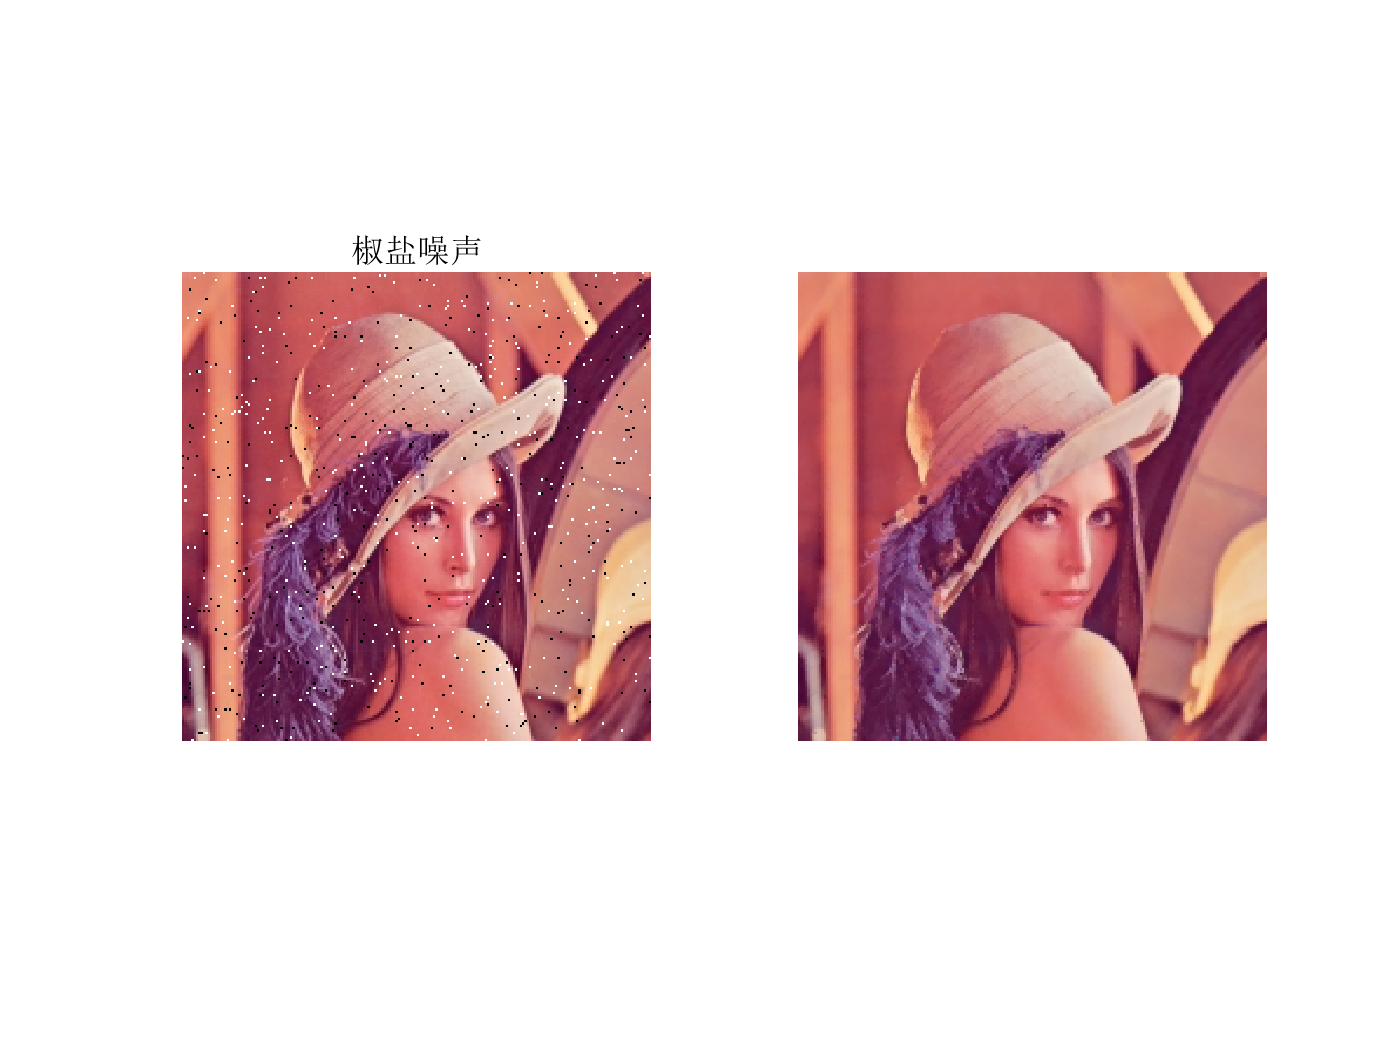

img = imread("lena.jpg");
[l,w,ch] = size(img);
img = double(img);

figure;
a = 0.01; b = 0.01;
X = rand(l,w); Y = rand(l,w);
c = X <= a;
noise_saltpepper = c;
c = Y >= 1-b;
noise_saltpepper = noise_saltpepper - 2*c;
img_sp = img + 255*noise_saltpepper;
subplot(121);
imshow(uint8(img_sp));
title('椒盐噪声');

res = adaptive_mid_filter(uint8(img_sp),5);
subplot(122);
imshow(uint8(res));